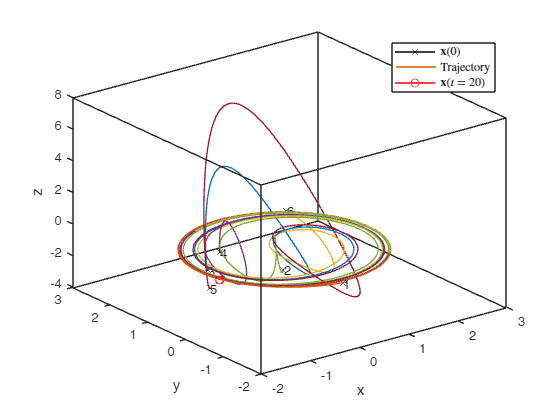

clear all
clc
global A B C K F n m d Hbar W na Z
d = 3; n = 6; m = 8;
na = 1;
s = [1 1 2 2 3 3 4 5];
t = [2 4 3 5 4 6 5 6];
G = graph(s,t);
H = incidence(G)'*eye(6);
A12 = [1 0 0; 0 2 1; 0 1 2];
A25 = eye(3); 
A34 = A25;
A14 = [2 2 0; 2 2 0; 0 0 1];
A36 = A14;
A23 = [2 0 0; 0 0 0; 0 0 1];
A56 = A23;
A45 = [0 0 0; 0 1 0; 0 0 2];

W = blkdiag(A12,A14,A23,A25,A34,A36,A45,A56);

Hbar = kron(H,eye(d));
L = Hbar'*W*Hbar;
rng(2);
x0 = 4*(rand(d*n,1)-0.5);
xhat0 = rand(d*n,1);
eta0 = rand(d*n,1);
c0 = 0.1*rand(m,1);

r0 = [x0;xhat0;eta0;c0];
%options = odeset('RelTol',1e-7,'AbsTol',1e-6);

A = [0 1 1;-1 0 1;0 0 -1];
B = [0; 0; 1];
C = [1, 0, 2];
K = place(A, B, [-2+j,-2-j, -2]);
F = place(A', C',[-3 -4 -5]); F = F';
eig(A - B*K);
eig(A - F*C);
Z = [zeros(d,d) zeros(d,d*(n-na));
     zeros(d*(n-na),d) eye(d*(n-na))];

[t,r] = ode45(@control_law,[0:0.01:20],r0);
t_end = length(t);

% Plotting
str3 ='#C0C0C0';
color3 = sscanf(str3(2:end),'%2x%2x%2x',[1 3])/255;
r = r';
x = r(1:d*n,:);
x=x';
xhat = r(d*n+1:2*d*n,:); xhat = xhat';
eta = r(2*d*n+1:3*d*n,:); eta = eta';
c = r(3*d*n+1:end,:);

e = zeros(length(t),1);
for i=1:length(t)
    e(i,1) = norm(Z*L*x(i,:)');
end

figure
hold on;
for i=1:n
    plot3(x(1,d*i-d+1),x(1,d*i-d+2),x(1,d*i),'Marker','x','Color','k');
    plot3(x(:,d*i-d+1),x(:,d*i-d+2),x(:,d*i),'LineWidth',1);
    plot3(x(t_end,d*i-d+1),x(t_end,d*i-d+2),x(t_end,d*i-d+3),"Marker","o","Color","r");
    text(x(1,d*i-d+1),x(1,d*i-d+2),x(1,d*i),num2str(i),"Color",'k');
end
xlabel 'x'; ylabel 'y'; zlabel 'z';
ax = gca;
ax.BoxStyle = 'full';
box on
legend({'$\mathbf{x}(0)$','Trajectory','$\mathbf{x}(t=20)$'}, "NumColumns", 1,"Interpreter","latex")
view(3)

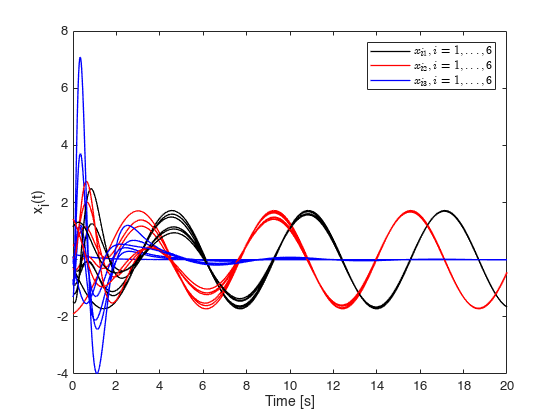

figure
hold on;
for i=1:n
   plot(t,x(:,3*i-2),'-k','LineWidth',1);
   plot(t,x(:,3*i-1),'-r','LineWidth',1);
   plot(t,x(:,3*i),'-b','LineWidth',1);
end
xlabel 'Time [s]'; ylabel 'x_i(t)';
box on;
legend({'$x_{i1}, i=1,\ldots,6$','$x_{i2}, i=1,\ldots,6$','$x_{i3}, i=1,\ldots,6$'},"NumColumns",1,"Interpreter","latex")

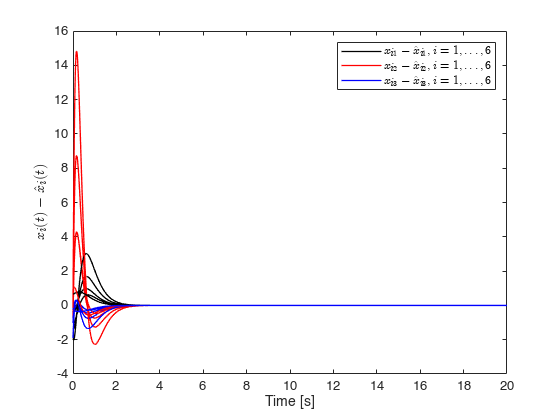


figure
hold on;
for i=na+1:n
   plot(t,x(:,3*i-2)-xhat(:,3*i-2),'-k','LineWidth',1);
   plot(t,x(:,3*i-1)-xhat(:,3*i-1),'-r','LineWidth',1);
   plot(t,x(:,3*i)-xhat(:,3*i),'-b','LineWidth',1);
end
xlabel 'Time [s]'; ylabel('$x_i(t)-\hat{x}_i(t)$',"Interpreter","latex");
box on;
legend({'$x_{i1}-\hat{x}_{i1}, i=1,\ldots,6$','$x_{i2}-\hat{x}_{i2}, i=1,\ldots,6$','$x_{i3}-\hat{x}_{i3}, i=1,\ldots,6$'},"NumColumns",1,"Interpreter","latex")

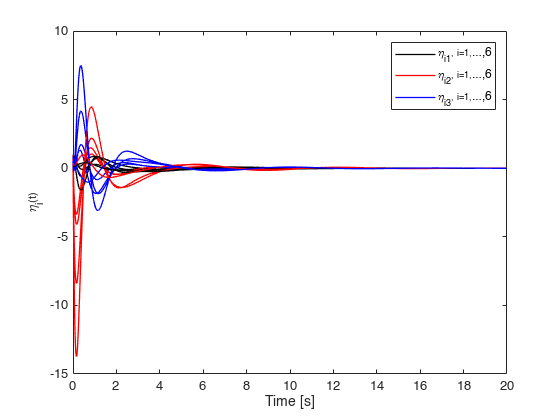


figure
hold on;
for i=na+1:n
   plot(t,eta(:,3*i-2),'-k','LineWidth',1);
   plot(t,eta(:,3*i-1),'-r','LineWidth',1);
   plot(t,eta(:,3*i),'-b','LineWidth',1);
end
xlabel 'Time [s]'; ylabel '\eta_i(t)';
box on;
legend({'\eta_{i1}, i=1,\ldots,6','\eta_{i2}, i=1,\ldots,6','\eta_{i3}, i=1,\ldots,6'},"NumColumns",1)

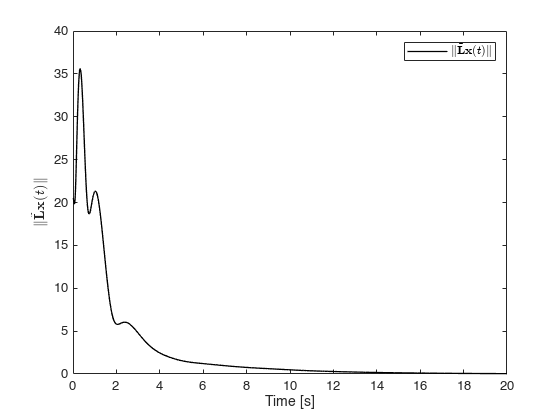


figure
hold on;
plot(t,e,'-k','LineWidth',1);
xlabel 'Time [s]'; ylabel('$\|\tilde{\mathbf{L}}\mathbf{x}(t)\|$', 'interpreter', 'latex');
box on;
legend({'$\|\tilde{\mathbf{L}}\mathbf{x}(t)\|$'}, "NumColumns", 1, 'interpreter', 'latex');

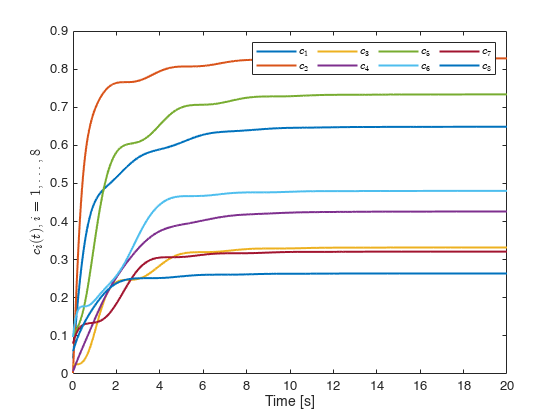


figure
hold on;
for i=1:m
    plot(t,c(i,:),'LineWidth',1.5);
end
xlabel 'Time [s]'; 
ylabel('$c_i(t),i=1,\ldots,8$', 'interpreter', 'latex');
box on;
legend({'$c_1$','$c_2$','$c_3$','$c_4$','$c_5$','$c_6$','$c_7$','$c_8$'}, "NumColumns", 4, 'interpreter', 'latex');

function dr = control_law(t,r)
    global A B C F K n m d Hbar W Z na
    x = r(1:d*n,1);
    xhat = r(d*n+1:2*d*n,1);
    eta = r(2*d*n+1:3*d*n,1);
    c = r(3*d*n+1:end,1);
    Lc = Hbar'*kron(diag(c),eye(d))*W*Hbar;
    zeta = xhat - eta;
    zeta(1:d*na,1) = x(1:d*na,1);
    dx = kron(eye(n),A)*x - kron(eye(n),B*K)*eta;
    dx(1:d*na,1) = kron(eye(na),A)*x(1:d*na,1);
    dxhat = kron(eye(n),A)*xhat + kron(eye(n),F*C)*(x-xhat) - kron(eye(n),B*K)*eta;
    deta = kron(eye(n),A-B*K)*eta + kron(eye(n),F*C)*(x-xhat) + Lc*zeta;
    
    dc = zeros(m,1);
    for i = 1:m
        p = Hbar(d*i-d+1:d*i,:)*zeta;
        dc(i,1) = 0.25*p'*W(d*i-d+1:d*i,d*i-d+1:d*i)*p;
    end
    dr = [dx;Z*dxhat;Z*deta;dc];
end